# Taller 2 - Control con controlador PID

- Miller Javier Arias Quintero

- Eric Santiago Guerrero

Para este taller es necesario encontrar o desarrollar un controlador con los conocimientos adquiridos, para este punto se escogio un PID aunque puede que no sea el usado en el laboratorio

%Función de transferencia
G

G =
 
         194.9
  --------------------
  s^2 + 0.58 s + 44.61
 
Continuous-time transfer function.
Model Properties


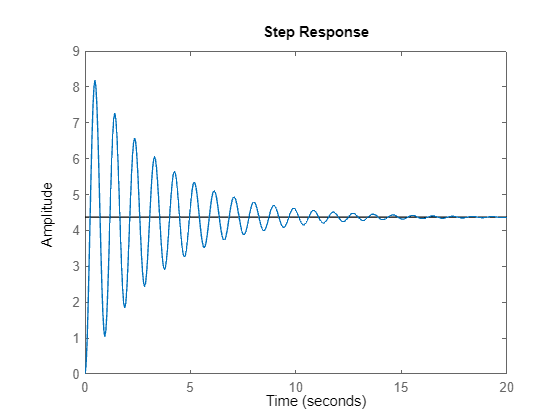

step(G)

Para esta función de transferencia, se probaron diversos controladores PID

%P
P

P =
 
  Kp = 0.221
 
P-only controller.
Model Properties


%PI Para el PI tenemos varias configuraciones las cuales harian el sistema

%muy rapido o muy lento
%Robusto y Lento
Drobusto

Drobusto =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 8.72e-05, Ki = 0.00671
 
Continuous-time PI controller in parallel form.
Model Properties


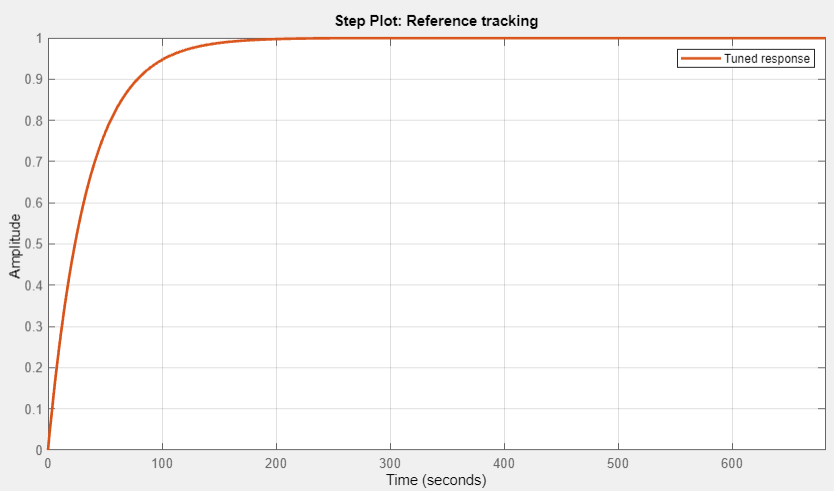

%Agresivo y rápido
Dagresivo

Dagresivo =
 
        1 
  Ki * ---
        s 

  with Ki = 0.0734
 
Continuous-time I-only controller.
Model Properties


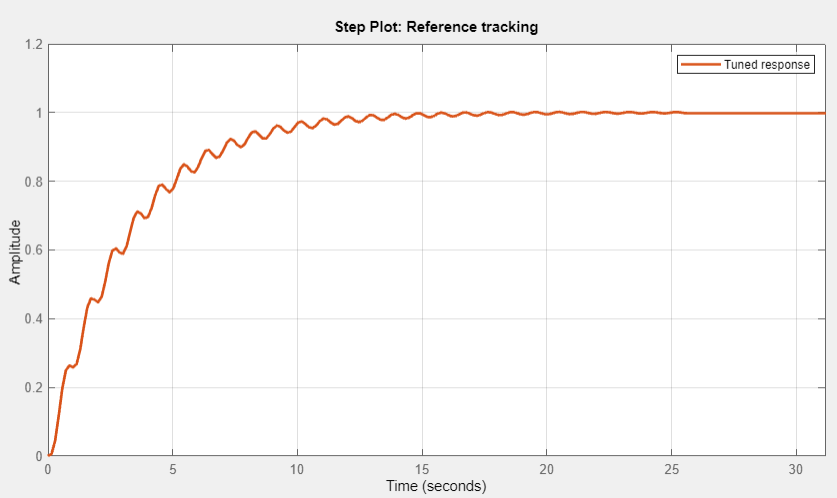

Para el PD, se obtiene una respuesta decente

PD

PD =
 
             
  Kp + Kd * s
             

  with Kp = 281, Kd = 1.83
 
Continuous-time PD controller in parallel form.
Model Properties


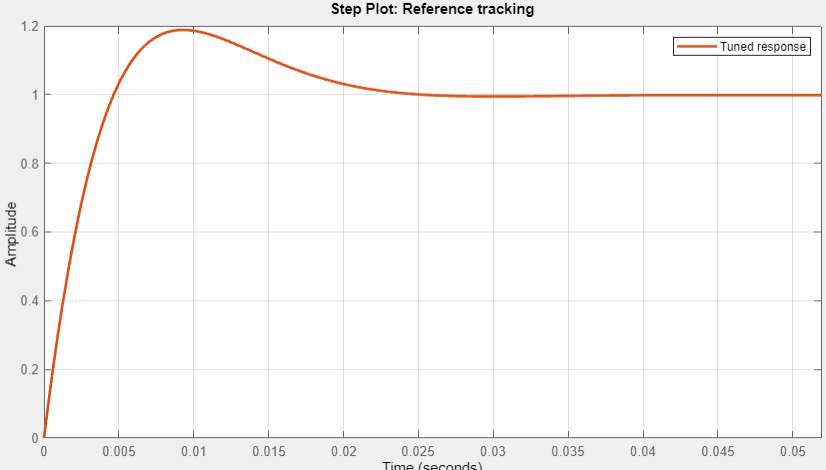

Para terminar implementamos un PID el cual nos elimina el sobrepico del PD

PID

PID =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 106, Ki = 712, Kd = 3.94
 
Continuous-time PID controller in parallel form.
Model Properties